# Parameter Estimation for Continuous-SIR models

Localities = ["Germany", "Korea"];

time = {40:240; 30:250};
Population = [8.3e7; 5.1e7];
ydata = cell(length(Localities),1);

for i = 1: length(Localities)
    load('../Data/' + Localities(i) + '.mat')
    ydata_aux = [Cases-Recovered-Death; Recovered];
    ydata{i} = ydata_aux(:,time{i});
end

VarNames = {'S_f','S_q','I_f','I_q','I_j','R','R_j'};
OutNames = {'S_f','S_q','I_f','I_q','I_j','R','R_j', '\aleph', 'G(t)'};
ParNames = {'\lambda','\alpha','\mu', '\theta', '\gamma', '\nu', 'z', '\beta'};

FullNames = [VarNames,ParNames];

ModelNames = ["Simple", "Complex", "Classic"];

T_save = cell(length(Localities), length(ModelNames));  

for k = 1:length(Localities)
    
    RealData = ydata{k};    
    
    Range1 = [ Population(k) Population(k);    %S_f
               0 0;                     %S_q 
               0 1000;                  %I_f 
               0 0;                     %I_q
               RealData(1,1) RealData(1,1);    %I_j
               0 1000;                         %R
               RealData(2,1) RealData(2,1);    %R_j
        ];
    
    Range2 = [ 0 3;%lambda 
               0 4;    %alpha 
               0 0;  %mu 
               0 4;    %theta 
               0 4;    %gamma 
               0 1000;  %nu 
               0 30;    %z 
               0 4;    %beta 
    ];
    
    RangeT = [Range1; Range2];
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    N = 1000;
    extra = struct();
    Parameters = [];
    Res = [];
     
    for i = 1:3
        
        extra.Prob = i;
        %%Prob = 1 -> psi(simple)
        %%Prob = 2 -> phi(complex)
        %%Prob = 3 -> classical
        
        [T,~] = gsua_dataprep("CHIMERA_FQ_continuous", RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames,'opt', extra);
        outs = 5; 
        T.Properties.CustomProperties.output = outs;
        
        if i == 3
            T.Range(end-1,:) = [0 0];
            T.Nominal(end-1) = 0;
        end
        
        if i == 2
            T.Range(end-2,:) = [0 300000];
        end
        
        T_save{k, i} = T;
        
        Solver = 'lsqc';
           
        Opt = optimoptions('lsqcurvefit', 'UseParallel', false,'MaxFunctionEvaluations', 3000, ...
            'MaxIterations', 300, 'Display','off');
        
        parfor j = 1:N
    %     for j = 1:N
            [T_aux, Res_aux] = gsua_pe(T, xdata, RealData(1,:),...
                'solver', Solver,'N', 1,'opt', Opt,'save', false);
            Parameters(:,j) = T_aux.Estlsqc;
            Res(j) = Res_aux;
        end
        
        [Res, idx] = sort(Res);
        Parameters = Parameters(:,idx);     
        T_save{i}.Nominal = Parameters(:,1);
        save("ResultsCovid/Estimations_Cont_" + Localities(k) + "_Aleph_" + ModelNames(i), "Res",  "Parameters")
        
        figure
        gsua_eval(Parameters(:,1), T_save{k, i}, xdata, RealData(1,:));
        suptitle(ModelNames(i) + " residual: " + Res(1) + " Locality:" + Localities{k})
    end
end

Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function


[T,~] = gsua_dataprep("CHIMERA_FQ_continuous", RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames);

Setting environment to work with user-defined function


outs = [5]; 
T.Properties.CustomProperties.output = outs;
T_aux = [];
for k = 1:length(Localities)
%     Localities(k)
    for i = 1:3
    load("ResultsCovid/Estimations_Cont_" + Localities(k) + "_Aleph_" + ModelNames(i))
    T_aux = [T_aux, Parameters(:,1)];
%     ModelNames(i)
    end
end
T.Params = T_aux;
T

T = 9×3 table
                 Range      Nominal       Params   
               _________    _______    ____________

    I_f        0    1000      500      [1×6 double]
    R          0    1000      500      [1×6 double]
    \lambda    0       3      1.5      [1×6 double]
    \alpha     0       4        2      [1×6 double]
    \theta     0       4        2      [1×6 double]
    \gamma     0       4        2      [1×6 double]
    \nu        0    1000      500      [1×6 double]
    z          0      30       15      [1×6 double]
    \beta      0       4        2      [1×6 double]


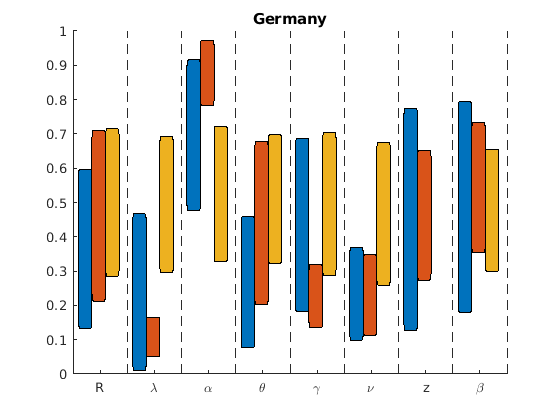

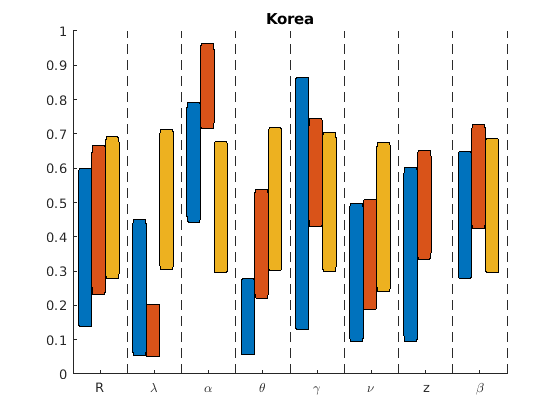

close all
for k = 1 :2
figure
FolderFigures = "/MATLAB Drive/CHIMERITApaper/Figures/";
A = rand(3,3);
cm = colormap(lines(size(A,1)));
x=[];
mx=[];
P=[];

for i=1:3
    load("ResultsCovid/Estimations_Cont_" + Localities(k) + "_Aleph_" + ModelNames(i))
    P = (Parameters-T_save{k, i}.Range(:,1))./(T_save{k, i}.Range(:,2)-T_save{k, i}.Range(:,1));
    
    for j = 1:9
        if i ~= 3 || j ~= 8 
            Pq = rmoutliers(P(j,:),'percentiles', [10 90]);
            Pq = quantile(Pq',[0.25 0.75])';
    %         Pq = [min(Pq) max(Pq)]';
            rectangle('Position',[j+0.25*(i-1) Pq(1) 1/4 Pq(2)-Pq(1)],'FaceColor',[cm(i,:),0.5],'Curvature',0.2)
            hold on
    %         text(0,j+0.75,string(T_save{k, i}.Properties.RowNames(j)))

        end
            x(j) = j+0.9;
            xline(x(j),'--')
            if j>1
                mx(j) = x(j-1)+(x(j)-x(j-1))/2;
            else
                mx(j) = (x(j)+1)/2;
            end          
    end
end

    xlim([min(x) max(x)])
    xticks(mx)
    set(gca,'XTickLabel',T_save{k, i}.Properties.RowNames,'TickLabelInterpreter', 'tex')
    title(Localities(k))    
%     savefig(FolderFigures + "PIA_" + Localities(k) + "Continuous.fig")
%     saveas(gcf,FolderFigures + "PIA_" + Localities(k) + "Continuous.png")
end

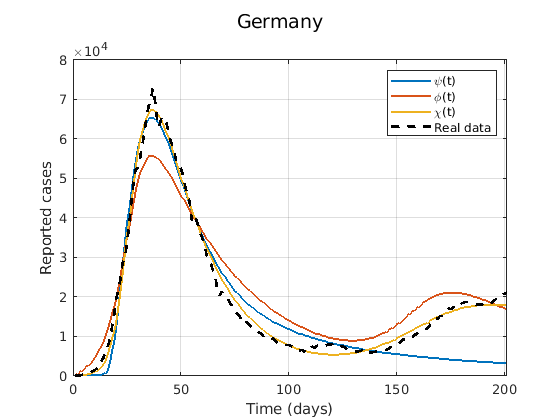

close all 

IdxSims = [];
Titles = ["\psi(t)"; 
    "\phi(t)";
    "\chi(t)";
    "Real data"];

for k = 1:length(Localities)
    
    A = rand(3,3);
    cm = colormap(lines(size(A,1)));
    
    counter = 1;
    RealData = ydata{k};    
    figure
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    for i = 1:3
        load("ResultsCovid/Estimations_Cont_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 2);
        T_save{k,i}.Properties.CustomProperties.output = 5;
        ysim = zeros(N, 1, D);
        for j = 1:N
            ysim(j,:,:) = gsua_deval(Parameters(:,j)', T_save{k,i}, xdata);
%             Res(j) = immse(squeeze(ysim(j,:,:)), RealData(1,:)');
    %         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
        end
        
        [~, Idx] = sort(Res);
        IdxSims(k) = Idx(1);
        
        for j = 1:1        
%             subplot(3,1,counter)
            plot(squeeze(ysim(IdxSims(k), j, :))', 'Color',cm(i,:),'LineWidth',1.5); 
            hold on
            grid on
%             title(Titles(counter))
            counter = counter +1;
            xlim([0 length(RealData)]);
        end
        suptitle(Localities(k))
    end
    xlabel("Time (days)")
    ylabel("Reported cases")
    hold on
    plot(RealData(j,:)','--k','LineWidth',2)
    legend(Titles)
%     savefig(FolderFigures + "Fit_" + Localities(k) + "Continuous.fig")
%     saveas(gcf,FolderFigures + "Fit_" + Localities(k) + "Constinuous.png")
end

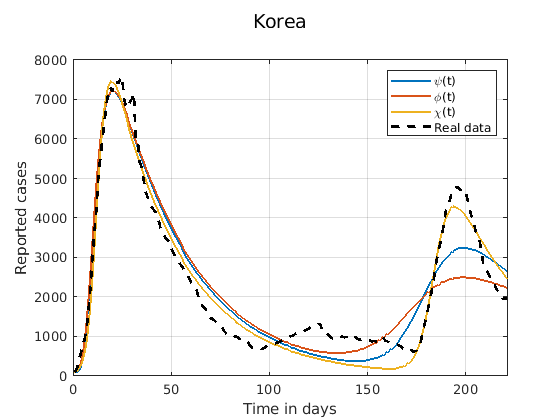

% legend({"Simulation", "Real data"}, 'location','best')
xlabel("Time in days")

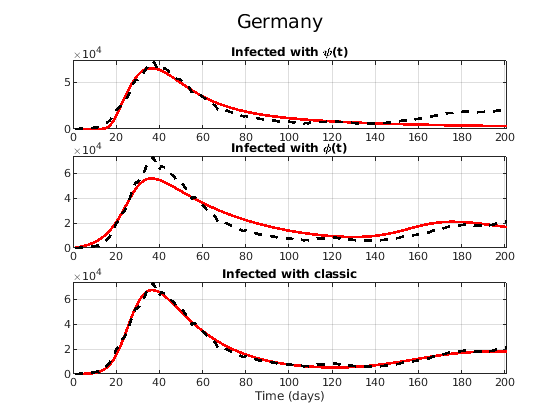

IdxSims = [];
Titles = ["Infected with \psi(t)"; 
    "Infected with \phi(t)";
    "Infected with classic"];
for k = 1:length(Localities)
    counter = 1;
    RealData = ydata{k};    
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    figure
    for i = 1:3
        load("ResultsCovid/Estimations_Cont_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 2);
        T_save{k,i}.Properties.CustomProperties.output = 5;
        ysim = zeros(N, 1, D);
        for j = 1:N
            ysim(j,:,:) = gsua_deval(Parameters(:,j)', T_save{k,i}, xdata);
%             Res(j) = immse(squeeze(ysim(j,:,:)), RealData(1,:)');
    %         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
        end
        
        [~, Idx] = sort(Res);
        IdxSims(k) = Idx(1);
        
        for j = 1:1        
            subplot(3,1,counter)
            plot(squeeze(ysim(IdxSims(k), j, :))', 'r','LineWidth',2); 
            hold on
            plot(RealData(j,:)','--k','LineWidth',2)
            grid on
            title(Titles(counter))
            counter = counter +1;
            xlim([0 length(RealData)]);
        end
        suptitle(Localities(k))
    end
    xlabel("Time (days)")
end

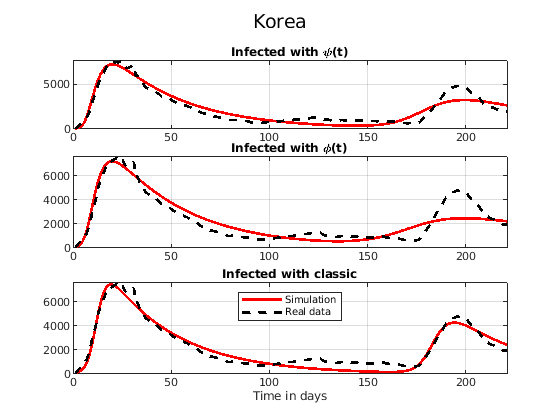

legend({"Simulation", "Real data"}, 'location','best')
xlabel("Time in days")

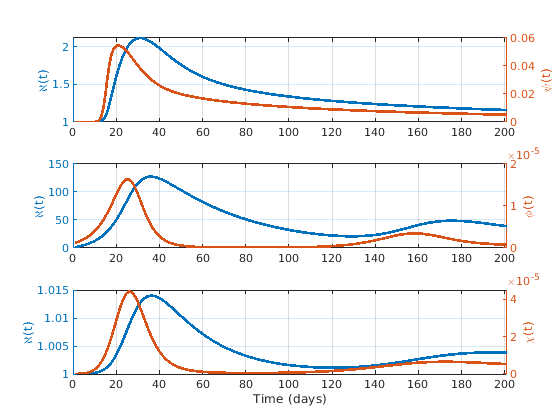

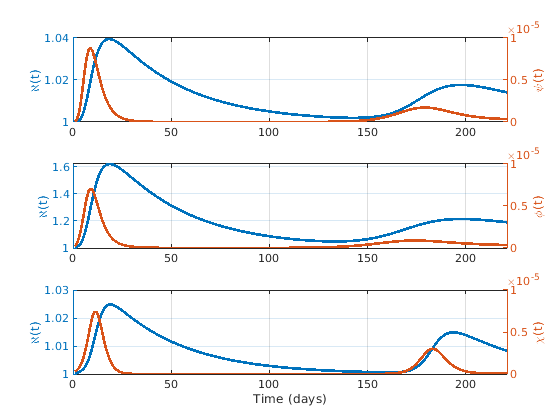

IdxSims = [];
Titles = ["Infected with \psi(t)"; 
    "Infected with \phi(t)";
    "Infected with classic"];
Prob = ["\psi(t)", "\phi(t)", "\chi(t)"];
for k = 1:length(Localities)
    counter = 1;
    RealData = ydata{k};    
    figure
    for i = 1:3
        load("ResultsCovid/Estimations_Cont_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 1);
        ysim = zeros(N, 2, D);
        T_save{k,i}.Properties.CustomProperties.output = [8,9];
        for j = 1:N
            ysim(j,:,:) = gsua_deval(Parameters(:,j)', T_save{k,i}, xdata);
%             Res(j) = immse(squeeze(ysim(j,:,:)), RealData(1,:)');
    %         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
        end
        
        [~, Idx] = sort(Res);
        IdxSims(k) = Idx(1);
        
        for j = 1:1        
            subplot(3,1,counter)
            yyaxis left
            plot(squeeze(ysim(IdxSims(k), j, :))','LineWidth',2); 
            ylabel("\aleph(t)")
            hold on
            yyaxis right
            plot(squeeze(ysim(IdxSims(k), j+1, :))','LineWidth',2);             
            ylabel(Prob(counter))
            grid on
%             title(Titles(counter))
            counter = counter +1;
            xlim([0 length(RealData)]);
        end
%         suptitle(Localities(k))
    end
%     legend("\aleph","Prob",'location','best')
    xlabel("Time (days)")    
%     savefig(FolderFigures + "Probs_" + Localities(k) + "Continuous.fig")
%     saveas(gcf,FolderFigures + "Probs_" + Localities(k) + "Continuous.png")
end

**Sensitivity analisys for estimation intervals for probaiblities**

probNames = ["psi", "phi","chi"]; 

N = 100000;
indexSA = [];
for i = 1:3
    M = gsua_dmatrix(T_save{2,i}, N, 'Method', 'Sobol');
    T_save{2,i}.Properties.CustomProperties.output = 10;
    T_SA{i} = gsua_sa(M,T_save{1,i});
    SUM = sum(T_SA{i}.Si)/sum(abs(T_SA{i}.Si));
    figure
    gsua_plot('Pie',T_SA{i},T_SA{i}.STi)
    title(Titles(i) + " Index:" + num2str(SUM))
%     figure
% %     gsua_plot('Bar',T_SA{i},T_SA{i}.STi)
%     savefig(FolderFigures + "SA_out_" + probNames(i) + "Discrete.fig")
%     saveas(gcf,FolderFigures + "SA_out_" + probNames(i) + "Discrete.png")
    indexSA = [indexSA, T_SA{i}.STi];
end

figure
indexSA=(indexSA-min(min(indexSA)))/(max(max(indexSA))-min(min(indexSA)));
[~, ixd] = sort(indexSA(:,1));
X = categorical(T.Properties.RowNames);
barh(X,indexSA(ixd,:))
legend({"\psi", "\phi", "\chi"}, 'location', 'best')
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'off';
savefig(FolderFigures + "SA_Prob_Bar_Continuous.fig")
saveas(gcf,FolderFigures + "SA_Prob_Bar_Continuous.png")

**Sensitivity analisys for estimation intervals for I_j**

indexSA = [];
N = 5e5
for i = 1:3
    M = gsua_dmatrix(T_save{2,i}, N, 'Method', 'Sobol');
    T_save{2,i}.Properties.CustomProperties.output = 5;
    T_SA{i} = gsua_sa(M,T_save{1,i});
    SUM = sum(T_SA{i}.Si)/sum(abs(T_SA{i}.Si));
    figure
    gsua_plot('Pie',T_SA{i},T_SA{i}.STi)
    title(Titles(i) + " Index:" + num2str(SUM))
%     figure
%     gsua_plot('Bar',T_SA{i},T_SA{i}.STi)
%     savefig(FolderFigures + "SA_Ij_" + probNames(i) + "Discrete.fig")
%     saveas(gcf,FolderFigures + "SA_Ij_" + probNames(i) + "Discrete.png")
    indexSA = [indexSA, T_SA{i}.STi];
end

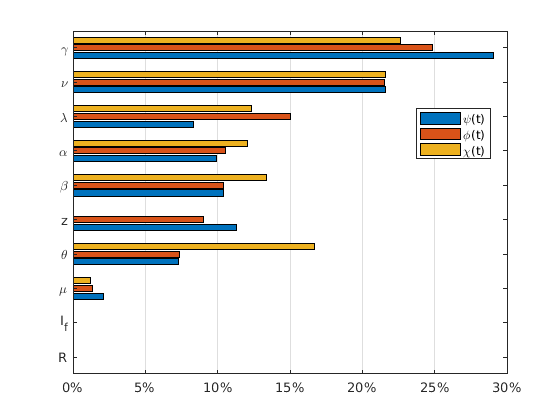

figure
indexSA2 = indexSA*100./(sum(indexSA));
[~, ixd] = sort(indexSA2(:,2));
% X = categorical(T.Properties.RowNames(ixd));
barh(indexSA2(ixd,:))
yticklabels(T.Properties.RowNames(ixd))
legend({"\psi(t)", "\phi(t)", "\chi(t)"}, 'location', 'best')
ax = gca;
ax.XGrid = 'on';
xtickformat('percentage')

savefig(FolderFigures + "SA_Ij_Bar_Continuous.fig")
saveas(gcf,FolderFigures + "SA_Ij_Bar_Continuous.png")

**UA**

Progress: 100%
Estimated processing time (h:m:s): 0:0:16
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:16
Estimated stop time (h:m:s): 10:54:26
Number of simulations: 1000


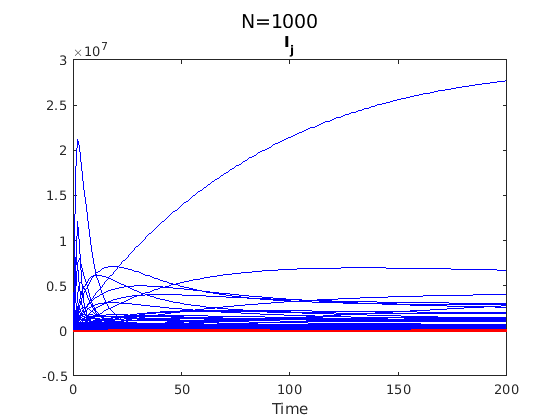

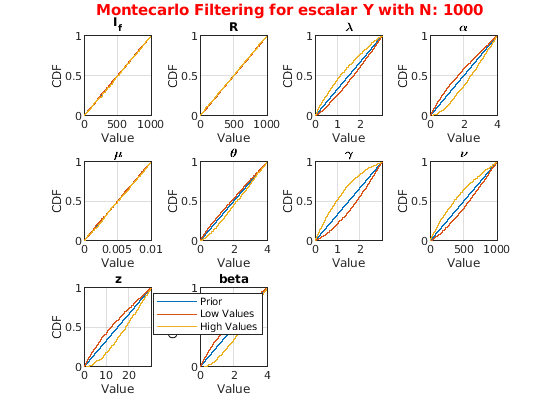

RealData = ydata{1}; 
 
N = 1000;
M = gsua_dmatrix(T_save{1,1}, N, 'Method','Sobol');  
gsua_ua(M, T_save{1,1},'xdata', xdata(1:201), 'ynom', RealData(1,:), 'parallel', false);

Progress: 100%
Estimated processing time (h:m:s): 0:0:21
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:21
Estimated stop time (h:m:s): 10:54:49
Number of simulations: 1000


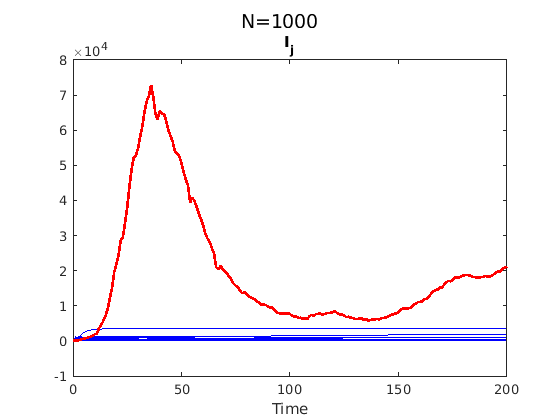

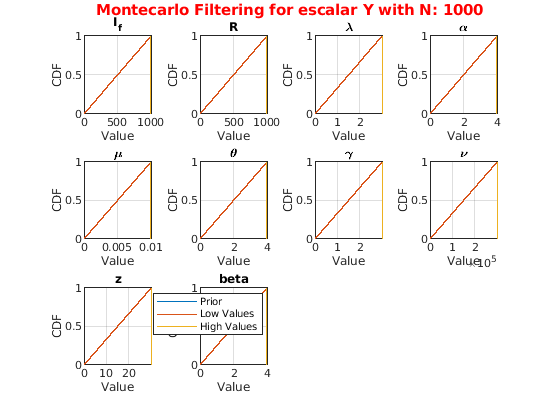

M = gsua_dmatrix(T_save{1,2}, N, 'Method','Sobol');  
gsua_ua(M, T_save{1,3},'xdata', xdata(1:201), 'ynom', RealData(1,:), 'parallel', false);

Progress: 100%
Estimated processing time (h:m:s): 0:0:29
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:29
Estimated stop time (h:m:s): 10:55:25
Number of simulations: 1000


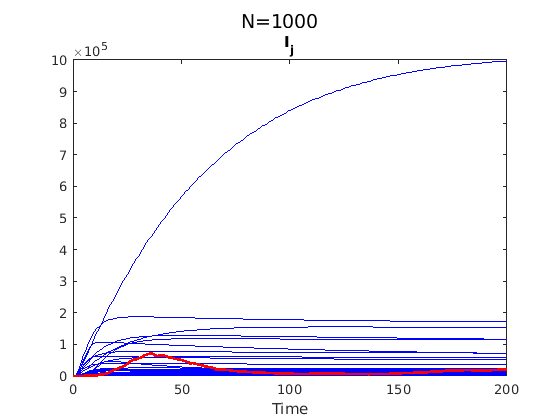

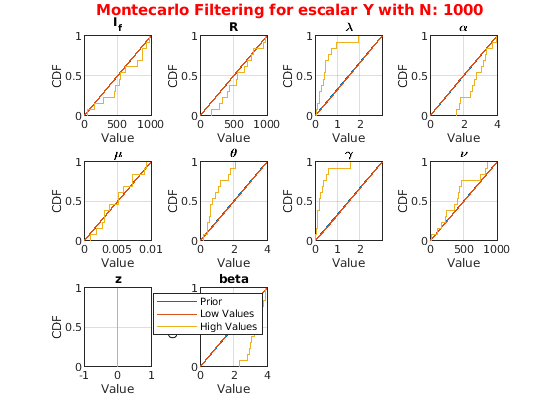


M = gsua_dmatrix(T_save{1,3}, N, 'Method','Sobol');  
gsua_ua(M, T_save{1,3},'xdata', xdata(1:201), 'ynom', RealData(1,:), 'parallel', false);